close all
clear
clc


## Signal generator test

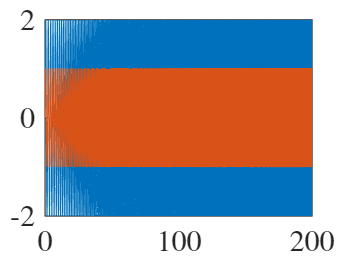

t0 = 0;
tf = 200;
% dfdt = 0.5;
ff = 2; 
% dt = 1./(5*ff);
dt = 0.001;
f0 = 0.5; % [Hz]
timevec = t0:dt:tf;

f_signal = f0 + (ff-f0) * (timevec - t0)./(tf-t0);
A = 2; 
signal = A*sin(2*pi*f_signal.*timevec);
signal_normalized = signal./max(abs(signal));

plot(timevec, signal);
hold on;
plot(timevec, signal_normalized)

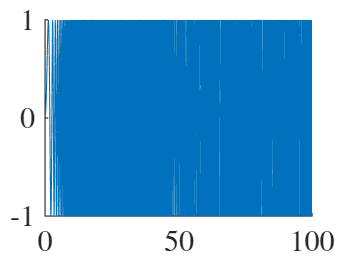

clear
clc

% Linear sine sweep
params.t0 = 0;
params.T = 0.5;
params.tf = 100;
params.dt = 1/1000;
params.ff = 15;
params.f0 = 0.01;

[signal, timevec, faxis] = GenerateInput(params, 1);

signal_plot = figure;
hold on;
plot(timevec, signal)

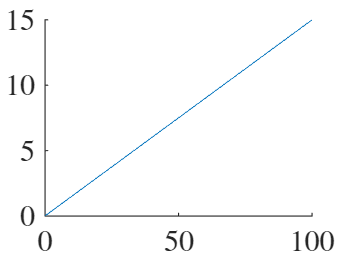


freqs_plot = figure;
hold on;
plot(timevec, faxis)

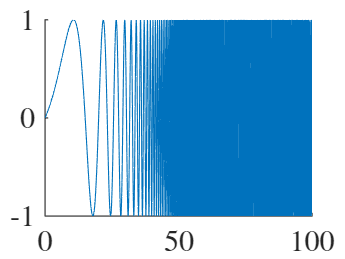


% Logarithmic sine sweep
params.t0 = 0;
params.dt = 1/1000;
params.tf = 100;
params.beta = 0.08;
params.f0 = 0.01;

[signal, timevec, faxis] = GenerateInput(params, 2);

figure();
hold on;
plot(timevec, signal)

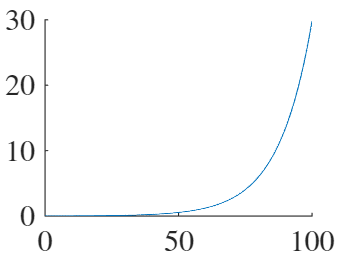


figure();
hold on;
plot(timevec, faxis)

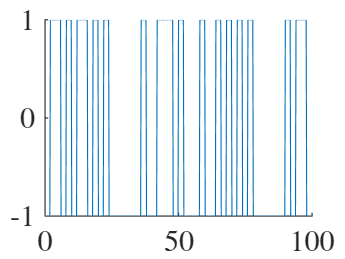


% RBS
params.t0 = 0;
params.tf = 100;
params.T = 2;


[signal, timevec, faxis] = GenerateInput(params, 3);

figure();
hold on;
plot(timevec, signal)

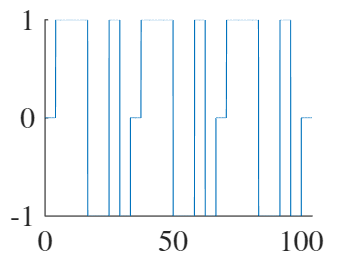


% figure(freqs_plot);
% hold on;
% plot(timevec, faxis)

% 3211 signal
params.N = 3;
params.tf = 100;

[signal, timevec] = GenerateInput(params, 4);

figure();
hold on;
plot(timevec, signal)

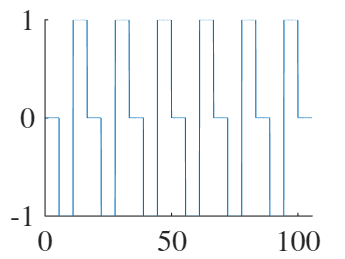


% Doublet
params.N = 6;
params.tf = 100;

[signal, timevec] = GenerateInput(params, 5);

figure();
hold on;
plot(timevec, signal)

T = 0.01
T =  1.4
T =  2.9
T =  4.3
T =  5.7
T =  7.1
T =  8.6
T =   10


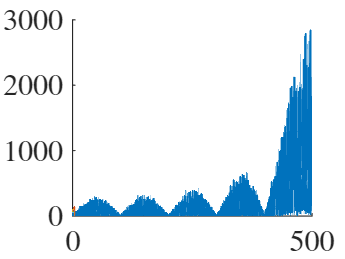

% Check what changes by varying T in RBS generation
close all
clear
clc

% RBS
params.t0 = 0;
params.tf = 100;
T_vec = linspace(0.01, 10, 8);

for idT = 1:numel(T_vec)

    params.T = T_vec(idT);
    [signal{idT}, timevec{idT}, faxis{idT}, S{idT}] = GenerateInput(params, 3);

    figure(1);
    hold on;
    fprintf("T = %4.2g\n", T_vec(idT));
    plot(faxis{idT}, abs(S{idT}), '-', 'Linewidth', 1.01);
    
end